Load the image of the heart. 

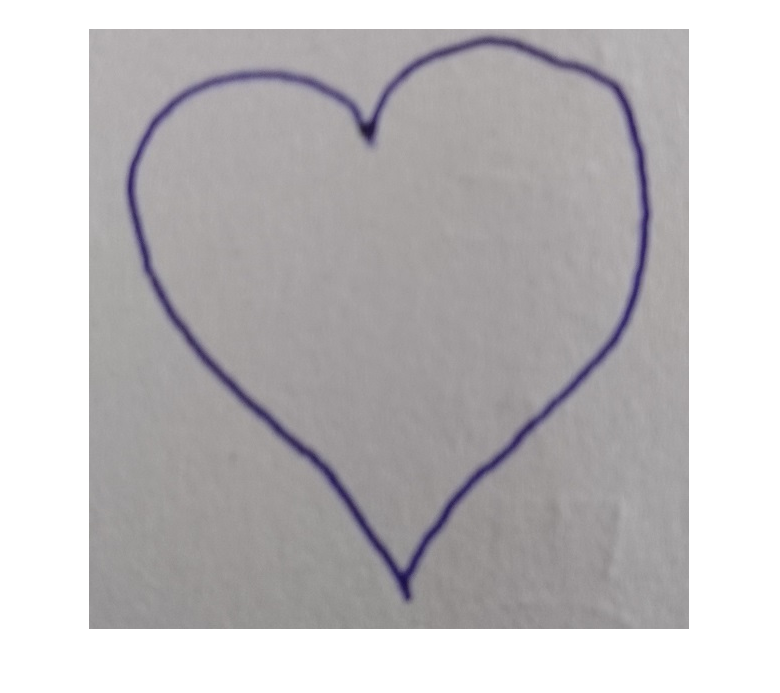

I = imread('heart.jpg');
imshow(I)

min(min(I(:,:,3)))

ans = uint8
51

max(max(I(:,:,3)))

ans = uint8
187

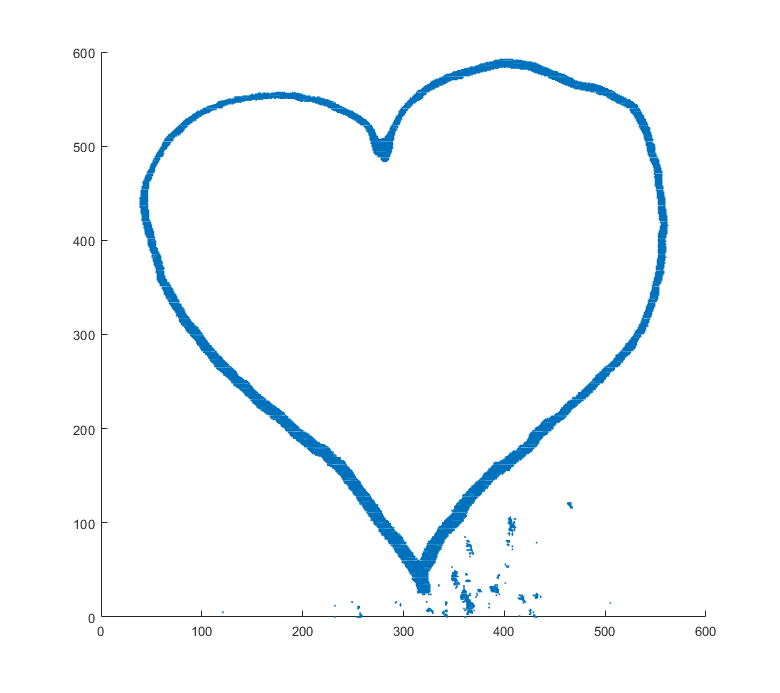


[row,col,v]=find(I(:,:,3)<140); %try 100,120,130,140
scatter(col,600-row,1)

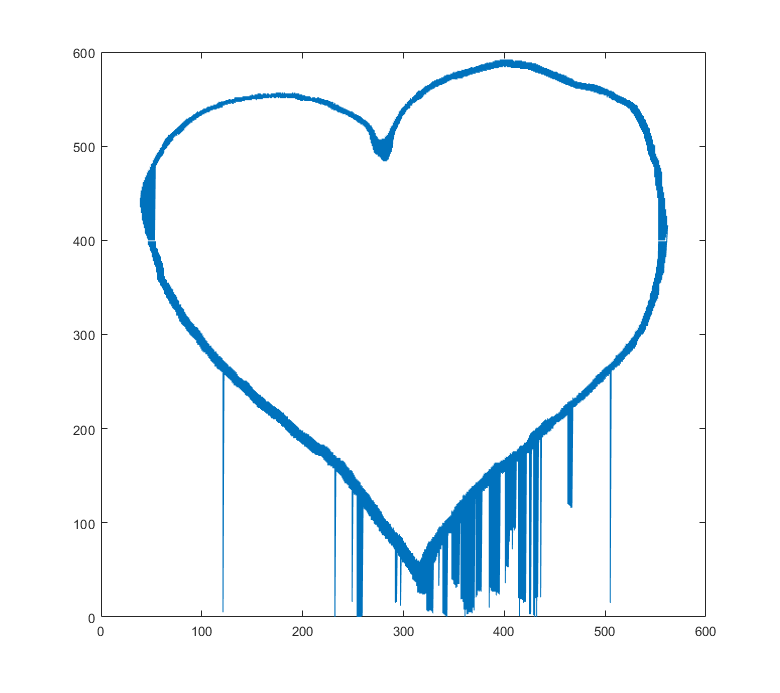

row=600-row;
col=[col(row<400);flip(col(row>=400))];
row=[row(row<400);flip(row(row>=400))];
plot(col,row)

n = 100;
indexes = round(linspace(1,length(col),n),0);

ans = 161

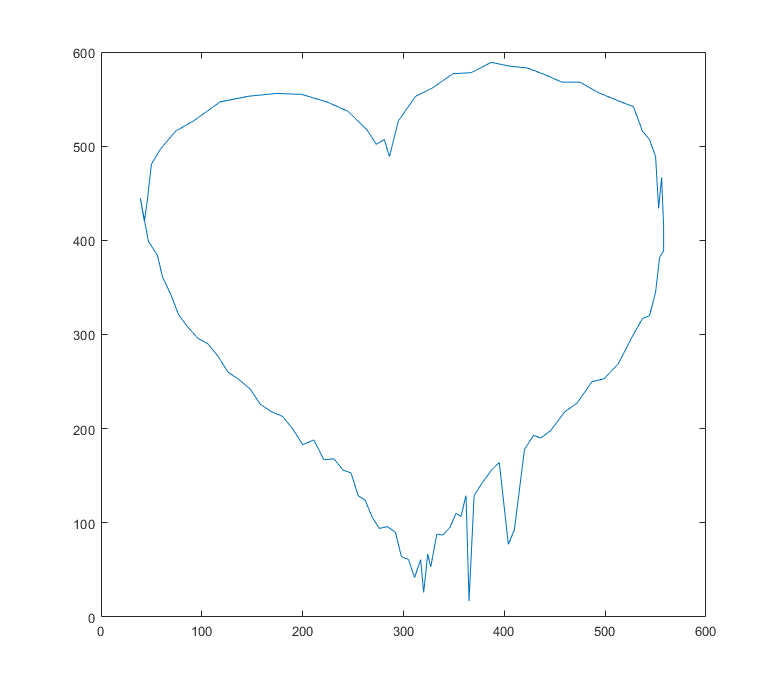

x = col(indexes);
y = row(indexes);
x = [x;x(1)];
y = [y;y(1)];
plot(x,y)

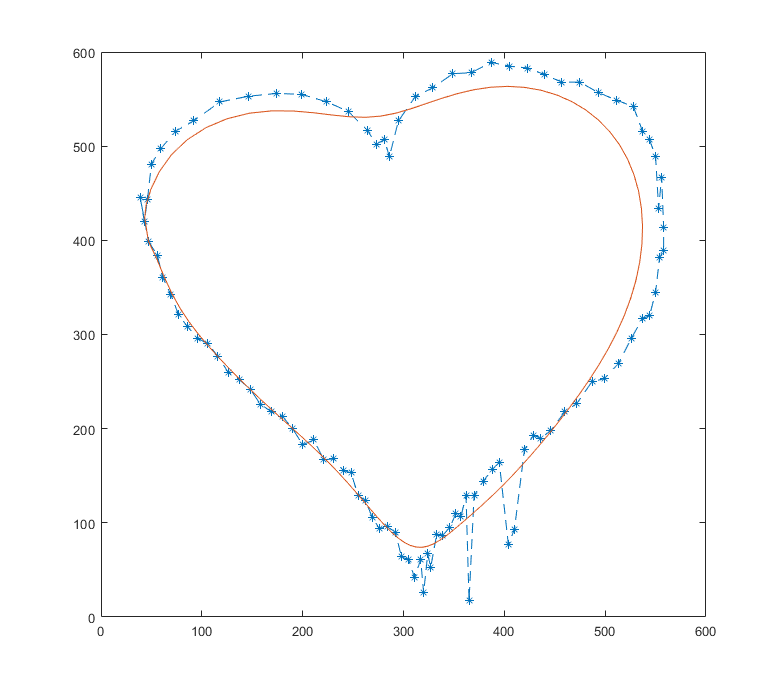

decastel(x,y,n)